# Edge Enhancement Algorithm Based on the Wavelet Transform for Automatic Edge Detection in SAR Images

Prepared for Dr. Oleg Michailovich

ECE 417 Image Processing Project

Prepared by: Awn Duqoum, Sasha Hall, Maya Deen

## 1. Problem Formulation

Satellite synthetic aperture radar (SAR) images are high-resolution images of large regions of the Earth. Radar images cannot be interpreted conventionally as their data is very heterogeneous, and must undergo pre-processing in order to extract meaningful interpretations from the data. This process is made more complex by the presence of speckle in SAR images, which is a multiplicative noise-like pattern. The problem presented in this report is edge detection in SAR images. 

## 2. Proposed Solution

The proposed solution is based on the algorithm from the paper *Edge Enhancement Algorithm Based on the Wavelet Transform for Automatic Edge Detection in SAR Images. *It is composed of two parts: edge enhancement followed by edge detection. 

The following is a high level overview of the edge enhancement algorithm:

- Take the logarithm of the input signal

- Take the 2D stationary wavelet transform, which produces 4 frequency bands: horizontal (H), vertical (V), diagonal (D), and the low-pass-filtered component of the image

- For each subband, take the absolute value and normalize to the maximum 

- Take the pointwise maximum of all three subbands {H, V, D}

- Combine the intermediate pointwise maxima through pointwise multiplication

After the edges of the image have been enhanced, a decision step is required to separate the input image into two classes: edges and no edges. In this solution a geodeic active contour algorithm is used to create a continuous, closed contour while minimizing noise and artifacts appearing in the output.

The algorithm for the geodesic active contour is:

- Define a starting surface u which is the outside contour of the input image

- Defining an update rate for the surface based on the input image, the current contour, and a constant erosion parameter

- Actualize the new surface by update the current surface using the learning rate determined in step 2

- Continue to update surface until the successive changes between surfaces is zero 

## 3. Data Sources

The simulated data source is constructed from a speckle matrix with an embedded square of increased intensity in the middle. The intensity of the square was changed by multiplying it with a constant value, m.

The speckle matrix is composed of random real and imaginary parts for elements. The randomly generated components are normally distributed with zero mean and variance equl to 0.5.

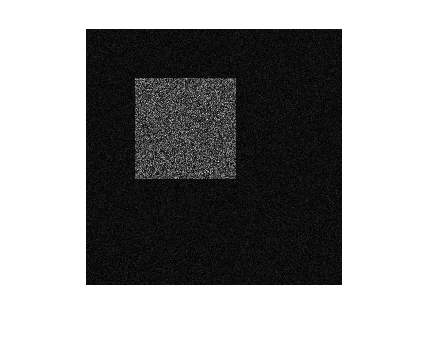

img_size = [256, 256];
m = 5; 

% Create the speckle pattern 
A = 0.5*randn(img_size) + 1i*0.5*randn(img_size);
A = abs(A);

% Create our superimposeed white squre object
A(50:150, 50:150) = m * A(50:150, 50:150);

imshow(A,[])

## 4. Solution

**2D Wavelet Transform of Mother Wavelet**

The wavelet transform is expressed as:


$$W_f \left(u,s\right)=\text{ }\int_{-\infty }^{\infty } f\left(x\right)\frac{1}{\sqrt{s}}\psi \ast \left(\frac{x-u}{s}\right)dx$$


The Haar wavelet was chosen as the mother wavelet for its linear phase, single vanishing moment and small number of coefficients. It is expressed as:


$$\psi \left(t\right)=\text{ }\left\lbrace \begin{array}{c}
1 & 0\le t<\frac{1}{2}\\
-1 & \frac{1}{2}\le t<1\\
0 & otherwise
\end{array}\right.$$


Therefore the wavelet transform becomes:


$$W_f \left(u,s\right)=\text{ }\frac{1}{\sqrt{s}}\int_u^{\frac{s}{2}+u} f\left(x\right)dx-\text{ }\frac{1}{\sqrt{s}}\int_{\frac{s}{2}+u}^{s+u} f\left(x\right)dx$$


By taking the logarithm of the original signal, the multiplicative speckle can be can be transformed to additive, signal independent noise with an approximately Gaussian distribution:


$$f(\tau) = \mbox{log}(\sigma(\tau)n(\tau)) = \mbox{log}(\sigma(\tau)) + \mbox{log}(n(\tau))$$


where $\sigma$ is the useful information and $n$ is the multiplicative noise component.

Substituting the logarithm of the signal into the wavelet transform:


$$W_f \left(u,s\right)=\text{ }\frac{1}{\sqrt{s}}\left\lbrack \int_u^{\frac{s}{2}+u} \left\lbrack log\left(\sigma \left(x\right)\right)+log\left(n\left(x\right)\right)\right\rbrack \text{dx}\right\rbrack -\text{ }\frac{1}{\sqrt{s}}\int_{\frac{s}{2}+u}^{s+u} \left\lbrack log\left(\sigma \left(x\right)\right)+log\left(n\left(x\right)\right)\right\rbrack \text{dx}$$



$$W_f \left(u,s\right)=\text{ }\frac{1}{\sqrt{s}}\left\lbrack \int_u^{\frac{s}{2}+u} \log \left(\sigma \left(x\right)\right)dx-\int_{\frac{s}{2}+u}^{s+u} \log \left(\sigma \left(x\right)\right)dx\right\rbrack +\frac{1}{\sqrt{s}}\left\lbrack \int_u^{\frac{s}{2}+u} \log \left(n\left(x\right)\right)dx-\int_{\frac{s}{2}+u}^{s+u} \log \left(n\left(x\right)\right)dx\right\rbrack$$


This can be further simplified knowing:


$$\int_u^{\frac{s}{2}+u} \mathrm{log}\left(n\left(x\right)\right)\mathrm{dx}-\int_{\frac{s}{2}+u}^{s+u} \mathrm{log}\left(n\left(x\right)\right)\mathrm{dx}\approx 0$$


Therefore,


$$W_f \left(u,s\right)=\;\frac{1}{\sqrt{s}}\left\lbrack \int_u^{\frac{s}{2}+u} \log \left(\sigma \left(x\right)\right)\textrm{dx}-\int_{\frac{s}{2}+u}^{s+u} \log \left(\sigma \left(x\right)\right)\textrm{dx}\right\rbrack$$


The size of the interval when using a single scale of the wavelet transform directly affects the precision of the localization of the edge and how much the result is affected by speckle. The proposed method uses a combination of several scales to use the advantages of the good sensitivity to discontinuitites of higher resolution scales and the good resolution of lower resolution ones. To combine the considered scales a interscale pointwise product is used. The statistical characteristics of the result of this multiscale product show the resulting distribution of probabilities is generally non-Gaussian heavy tailed. From this knowledge, an algorithm was devised.

A flowchart for the edge enhancement algorithm that is proposed is shown below.

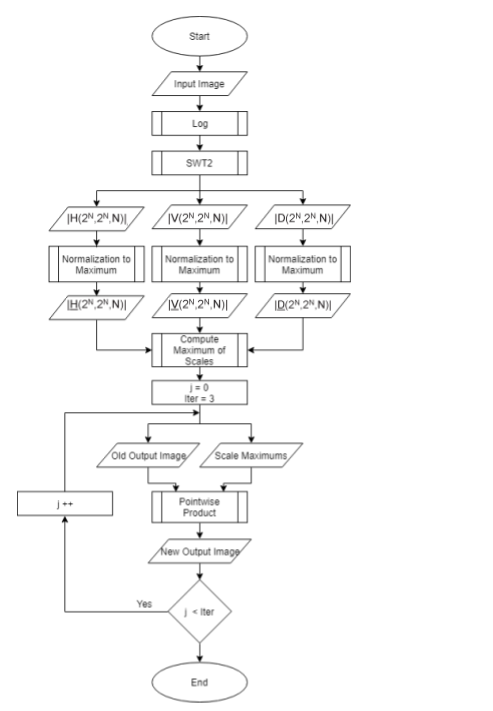

To start, the log of an input image is taken and then the H, V, and D frequency bands are obtained using SWT2. The next step normalizes these results to their maximum and takes their absolute value to then evaluate the pointwise maximum across all 3 subbands. Here is a flowchart which shows computing maximum scales in more detail.

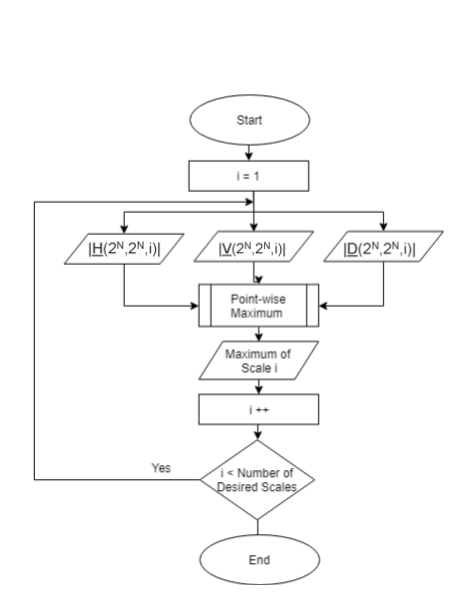

In this case the normalization factor is made to be 3 times the standard deviation. The maximum value is taken pixel per pixel to try and avoid speckle. This is done for different scales, after which the different maxima are combined through pointwise multiplication for each pixel.

An example of the use of this algorithm on an actual SAR image is shown here:

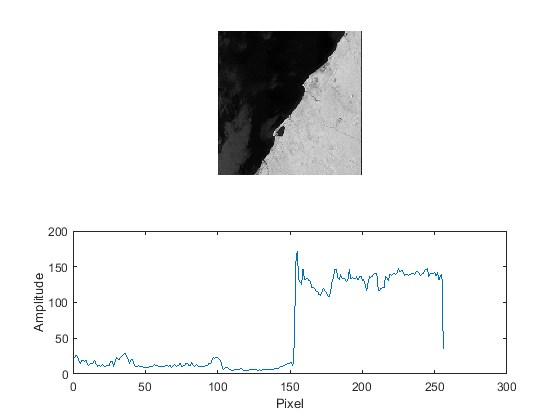

% Load the image and convert it to grayscale
img = rgb2gray(imread('test.png'));

% Make sure the image is in the right format
img = abs(double(imresize(img, 2.^floor(log(size(img))/log(2)))));

% Show the resules along with horizontal cut
DisplayImage(img);

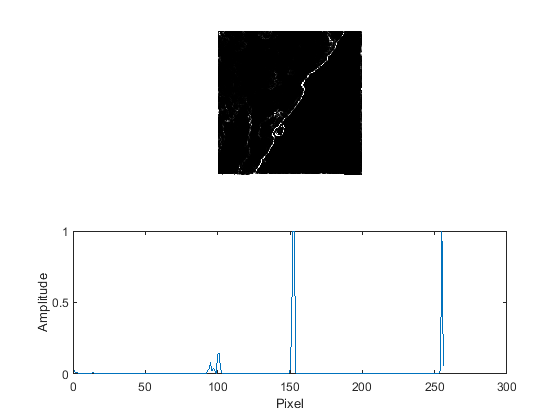

% Edge Enhancment
output_image = imadjust(EdgeEnhancement(img, 2));

% Show the resules along with horizontal cut
DisplayImage(output_image);

The edge enhancement function is shown below.

function [X_] = EdgeEnhancement( X, ittr)
    % Determine the scales we can use
    img_size = size(X);
    N = min(wmaxlev(img_size(1),'haar'), wmaxlev(img_size(2),'haar'));
    % Log 
    X = log(X);
    % SWT2
    [~,H,V,D] = swt2(X,N,'haar');
    %Abs
    H = abs(H);
    V = abs(V);
    D = abs(D);
    % Normalization to maxiumum
    for i = 1:N        
        H(:,:,i) = normalize(H(:,:,i));
        V(:,:,i) = normalize(V(:,:,i));
        D(:,:,i) = normalize(D(:,:,i));
    end
    % Loop
    if(nargin < 2)
        ittr = 3; % The paper reccomends 3 itterations
    end
    desired_scale = N; % Use the all allowable scales
    output_image = ones(img_size);
    for j = 1:ittr
        for i = 1:desired_scale
            % Pointwise maximum 
            max_scale = max(max(H(:,:,i), V(:,:,i)), D(:,:,i));
            output_image = output_image .* max_scale;
        end
    end
    X_ = output_image;
end

It uses a custom normalize function.

function [ X_] = normalize( X, feature )
    
    % If the image we are dealing with has no features (i.e vessels)
    % This method will work well, otherwise we will need to use 
    % another method, by deault assume no feature
    if(nargin < 2)
        feature = false;
    end
    
    if( feature == false)
        X_ = X ./ 3*std2(X);
        X_(X_>1) = 1;     
    else 
        X_ = X ./ max(max(x));
    end
end

The following function simply displays the image with a horizontal cut.

function [ ] = DisplayImage( X, row )
    % This function displays an image along with a hortizontal cut
    % If no row to cut is provided a default value of 100 is used
    if(nargin < 2)
        row = 100;
    end
    
    figure;
    subplot(2,1,1);
    imshow(X, []);
    subplot(2,1,2);
    plot(X(row,:));
    ylabel("Amplitude");
    xlabel("Pixel");

end

## 5. Results Visualization

## 6. Analysis & Conclusions

//Have you been able to reproduce the results reported in the original paper? Did the algorithm behave in a predictable way, i.e., as described by the authors? Do you own conclusions support those made by the  authors? What are the drawbacks (if any) of the proposed solution?)

## 7. Custom Algorithm Implementation Files

No custom source files/functions were used in addition to the code here.

## 8. References

//Add paper